# **亥姆霍兹线圈的磁力线绘制**

**        亥姆霍兹线圈是一对彼此平行且连通的共轴圆形线圈。两线圈内的电流方向一致，大小相同。线圈之间距离d正好等于圆形线圈的半径R。如下图所示:**

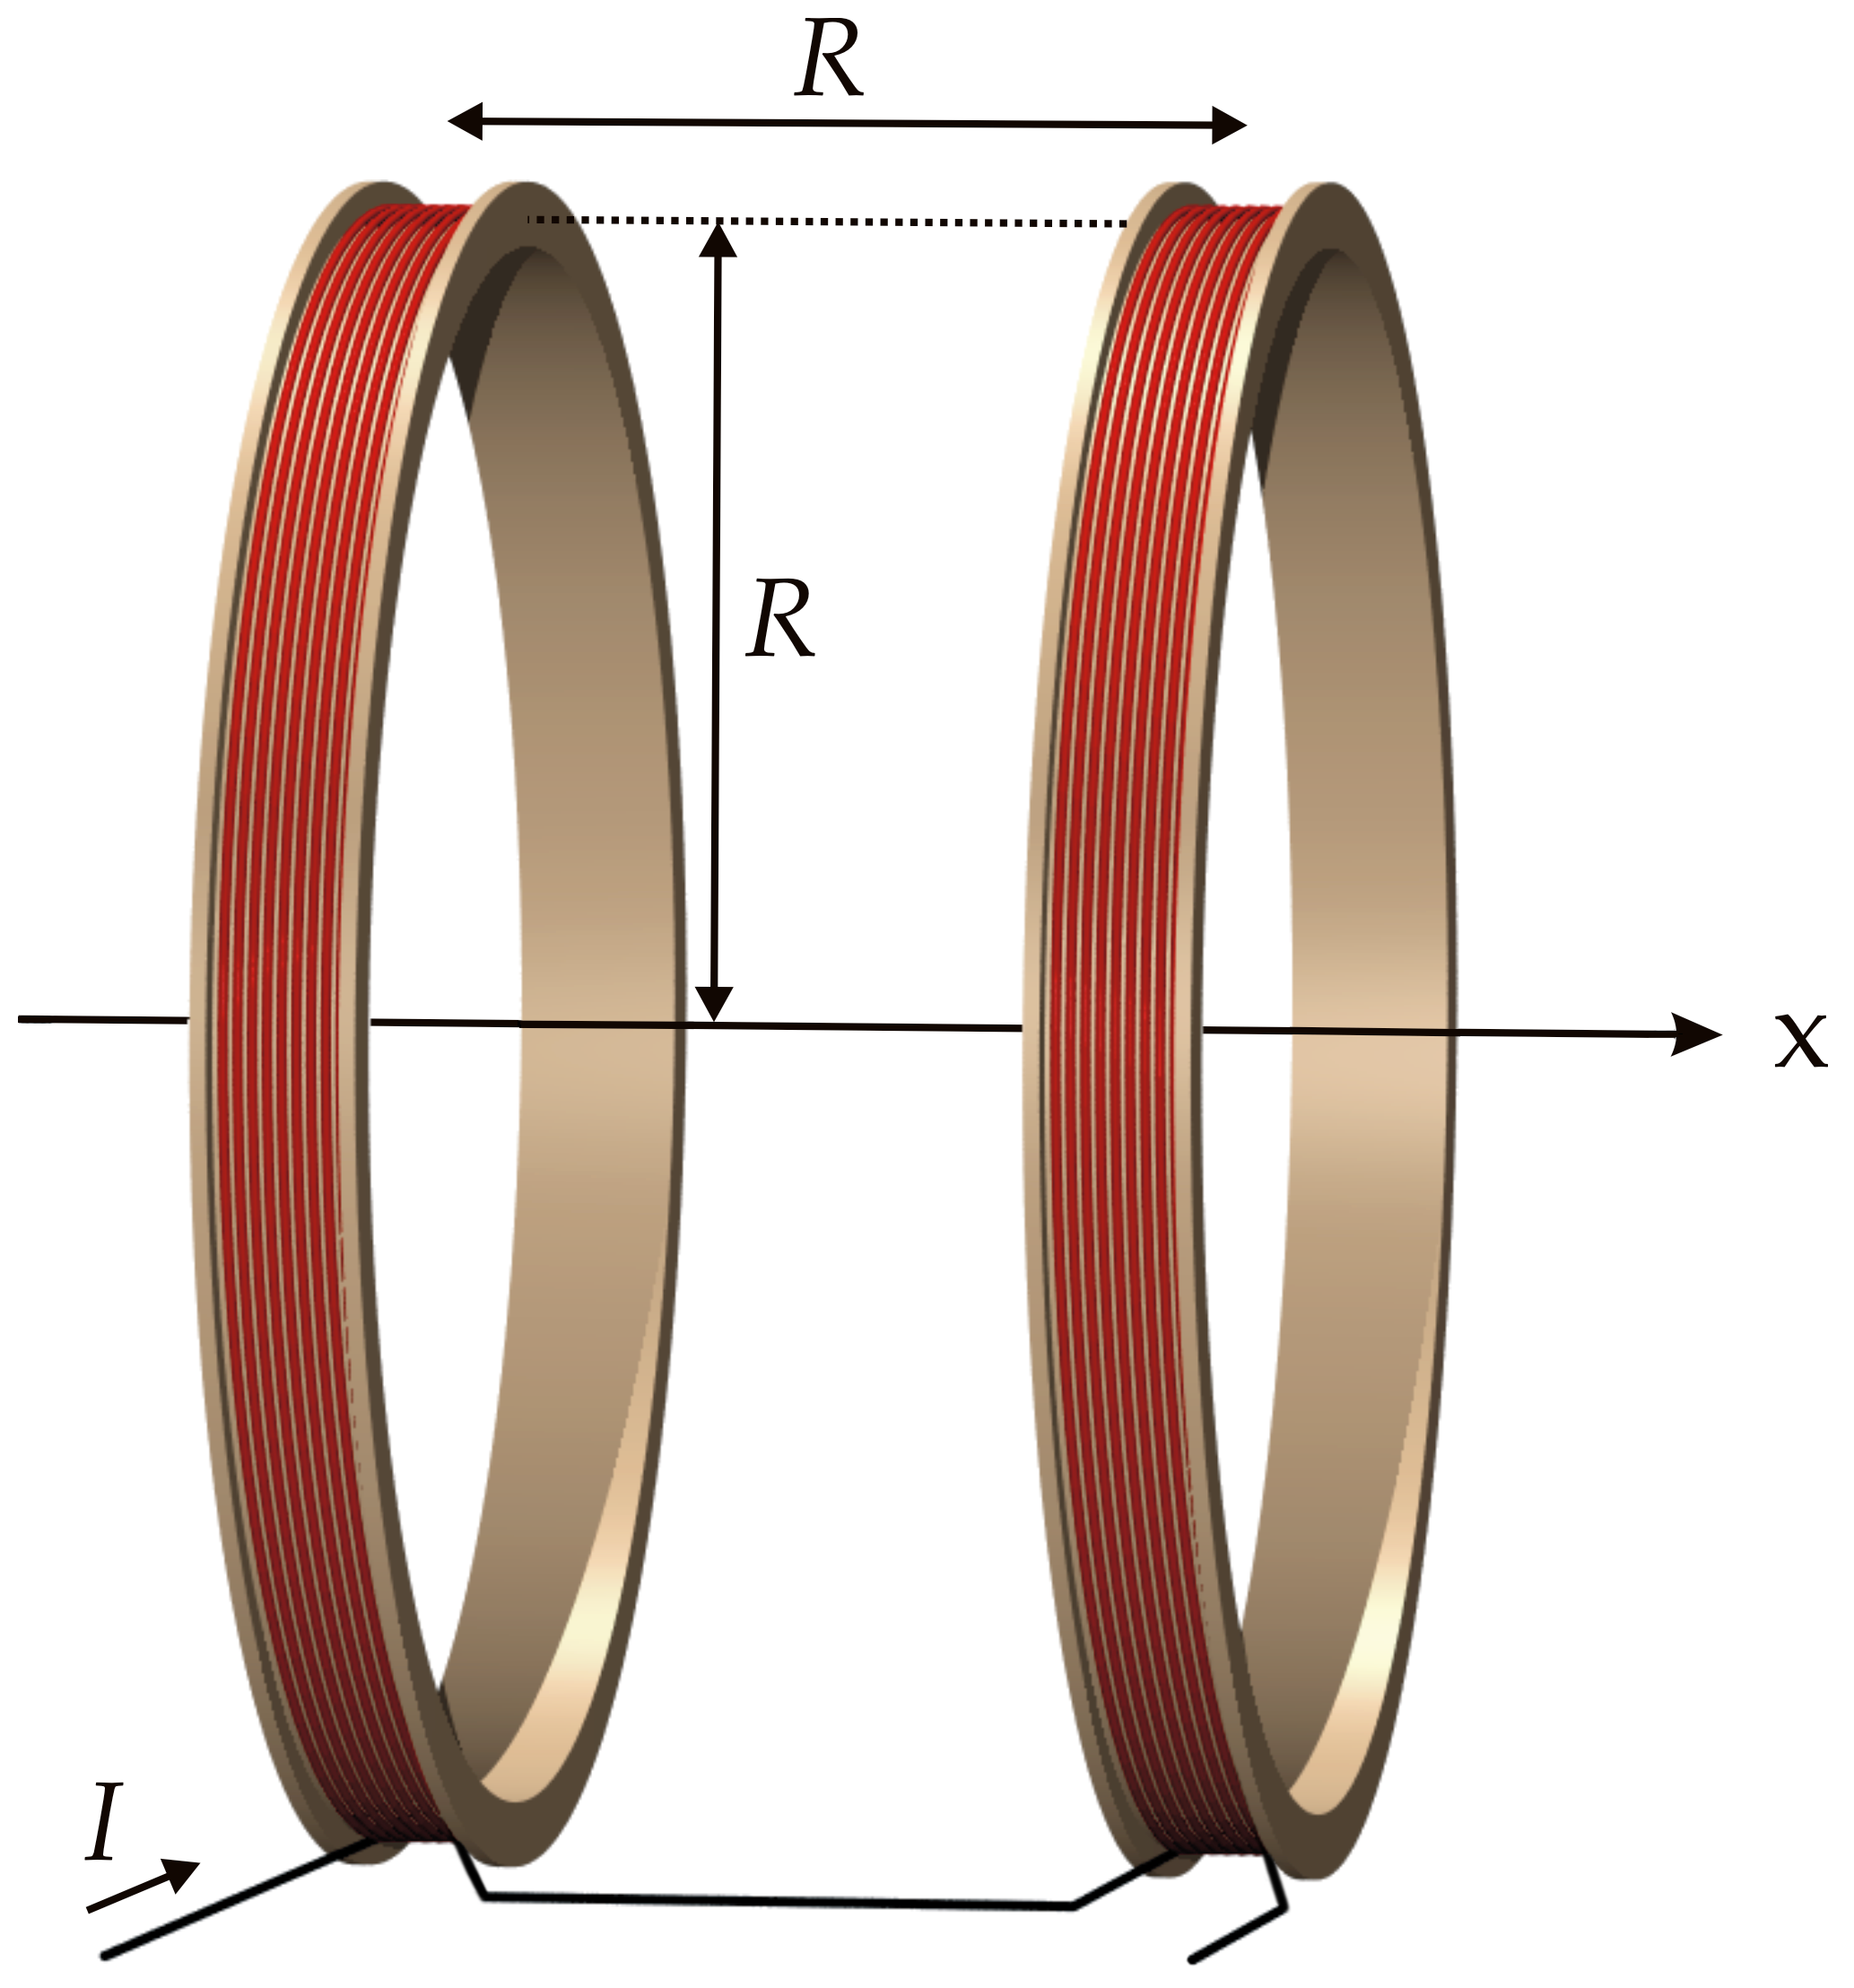

**        亥姆霍兹线圈是由两个相同的、彼此平行且连通的载流线圈组成，对于一个通电圆环而言，在通过其圆心且垂直于线圈平面的轴线附近任一点处，其磁场可由毕奥-萨伐尔定律计算给出：**$d\vec{\mathbf{B}} =\frac{\mu_0 }{4\pi }\frac{I\vec{\textrm{dl}} \times \vec{r} }{r^3 }$**，其中**$\vec{r}$**为电流元到场点的距离。由磁场叠加定理，亥姆霍兹线圈的磁场分布是两个通电圆圈磁场的叠加。**

**        在计算亥姆霍兹线圈磁感应强度大小的过程中，因为直接求取上述积分该过程较为复杂，故为了简化计算，我们在空间直角坐标系中，首先分别求取其在x轴，y轴和z轴的磁感应强度分量，然后求矢量和得到场点的磁感应强度，通过数值求和取代积分运算求出磁场分布，最后绘制磁场分布图和磁力线图。可知对亥姆霍兹线圈而言，两个线圈之外的磁场是逐渐减弱的，但是两个线圈轴线附近的一定区域内将产生较为均匀的叠加磁场。**

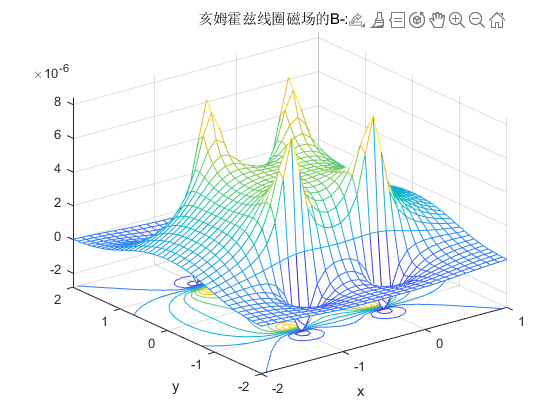

  MU0=4*pi*1e-7;                       	%真空中的磁导率
  I0=5;                 %自定义电流大小
  Rh=1;                 %自定义线圈半径
  C=MU0/(4*pi)*I0;                      %归并常数
  Nx=41;Ny=41;                          %观测点网格数
  x=linspace(-2*Rh,2*Rh,Nx);            %观测点范围
  y=linspace(-2*Rh,2*Rh,Ny);
  Nh=20;                                %电流环分段成电流元
  T0=linspace(0,2*pi,Nh+1);             %环的角度分段
  T1=T0(1:Nh);                          %电流元的起点角度
  yb=Rh*cos(T1);                        %电流元的起点坐标
  zb=Rh*sin(T1);
  T2=T0(2:Nh+1);                        %电流元的终点角度
  ye=Rh*cos(T2);                        %电流元的终点坐标
  ze=Rh*sin(T2);
  dlx=0;dly=ye-yb;dlz=ze-zb;            %电流元dl的三个长度分量
  xc=0;yc=(yb+ye)/2;zc=(zb+ze)/2;       %电流元中点的三个坐标分量
  %循环计算各网格点上的B(x,y)值
  for i=1:Ny 
      for j=1:Nx
          rx=x(j)-xc;ry=y(i)-yc;rz=0-zc;%电流元到场点的距离分量
          r3=sqrt(rx.^2+ry.^2+rz.^2).^3;
          dlXr_x=dly.*rz-dlz.*ry;       %计算dl和r叉乘结果的x，y，z分量
          dlXr_y=dlz.*rx-dlx.*rz;
          dlXr_z=dlx.*ry-dly.*rx;
          %把各段小电流元产生的磁场分量累加代替积分
          Bx(i,j)=sum(C*dlXr_x./r3);    %磁感应强度的x分量
          By(i,j)=sum(C*dlXr_y./r3);    %磁感应强度的y分量
          Bz(i,j)=sum(C*dlXr_z./r3);    %磁感应强度的z分量
      end
  end
  figure
  Bax=zeros(Nx,31);
  Bax(:,11:21)=Bx(:,11:21)+Bx(:,21:31); %两线圈内部的磁场x分量叠加
  Bax(:,1:11)=Bx(:,11:21)+Bx(:,1:11);   %左侧线圈左边部分磁场x分量叠加
  Bax(:,21:31)=Bx(:,31:41)+Bx(:,21:31); %右侧线圈右边部分磁场x分量叠加
  Bay=zeros(Ny,31);
  Bay(:,11:21)=By(:,11:21)+By(:,21:31); %两线圈内部的磁场y分量叠加
  Bay(:,1:11)=By(:,11:21)+By(:,1:11);   %左侧线圈左边部分磁场y分量叠加
  Bay(:,21:31)=By(:,31:41)+By(:,21:31); %右侧线圈右边部分磁场y分量叠加
  meshc(x(1:31),y,Bax);                  %画出B_x分布三维图
  xlabel('x');ylabel('y');
  title('亥姆霍兹线圈磁场的B-x分量');
  set(gcf,'Visible','on');   	    %强制图片弹出显示

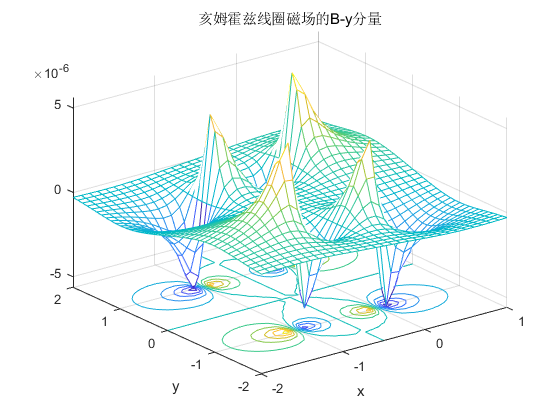

  figure
  meshc(x(1:31),y,Bay);                  %画出B_y分布三维图
  xlabel('x');ylabel('y');
  title('亥姆霍兹线圈磁场的B-y分量');
  set(gcf,'Visible','on');   	    %强制图片弹出显示

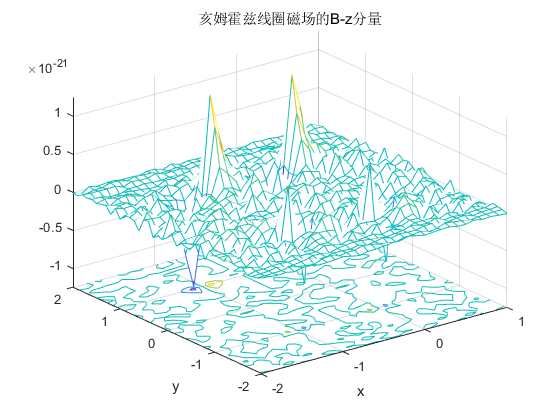

  figure
  Baz=zeros(Nx,31);
  Baz(:,11:21)=Bz(:,11:21)+Bz(:,21:31); %两线圈内部的磁场z分量叠加
  Baz(:,1:11)=Bz(:,11:21)+Bz(:,1:11);   %左侧线圈左边部分磁场z分量叠加
  Baz(:,21:31)=Bz(:,31:41)+Bz(:,21:31); %右侧线圈右边部分磁场z分量叠加
  meshc(x(1:31),y,Baz);                  %画出B_z分布三维图
  xlabel('x');ylabel('y');
  title('亥姆霍兹线圈磁场的B-z分量');
  set(gcf,'Visible','on');   	    %强制图片弹出显示

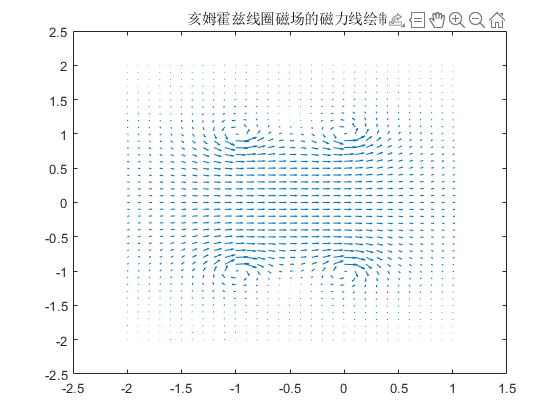

figure
%亥姆霍兹线圈磁力线绘制
[X,Y]=meshgrid(-2:0.1:2);
quiver(X(:,1:31),Y(:,1:31),Bax,Bay);
title('亥姆霍兹线圈磁场的磁力线绘制');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **参考文献：**

**                [1]周建,金建,刘道军等.Matlab仿真在亥姆霍兹线圈磁场测量实验中的应用研究[J].皖西学院学报,2017,33(02):50-53.**

**                [2]司文建,周楠,曹玉松.基于MATLAB的亥姆霍兹线圈轴线磁场均匀分布的动态仿真[J].许昌学院学报,2010,29(05):72-74.**